## **EXERCISE 3**

% Exercise 3
clc, clearvars, close all

**Task**: forecast the real price of gasoline for the US.

**Dataset**: gasoline.xlsx contains two monthly time series. The nominal price of gasoline and the CPI. 

- Create the real price of gasoline

- Plot real and nominal prices over time

- From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).

- Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable.

- Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)

- Transform the forecasts to levels (i.e. real prices)

- Compute the mean squared forecast error and comment.

data = readtable("gasoline_clean.xlsx");

% Rename variables
data = renamevars(data, ["observation_date", "GASREGW", "CPIAUCSL"], ...
    ["date", "nominal_price", "CPI"]);

% Make it a timetable
data = table2timetable(data);

data(1:6,1:2)

ans = 6×2 timetable
       date        nominal_price     CPI 
    ___________    _____________    _____

    01-Nov-1990        1.324        133.7
    01-Dec-1990        1.341        134.2
    01-Jan-1991         1.18        134.7
    01-Feb-1991       1.0942        134.8
    01-Mar-1991         1.04        134.8
    01-Apr-1991       1.0762        135.1


**1)  Create the real price of gasoline.**

**2) Plot real and nominal prices over time**

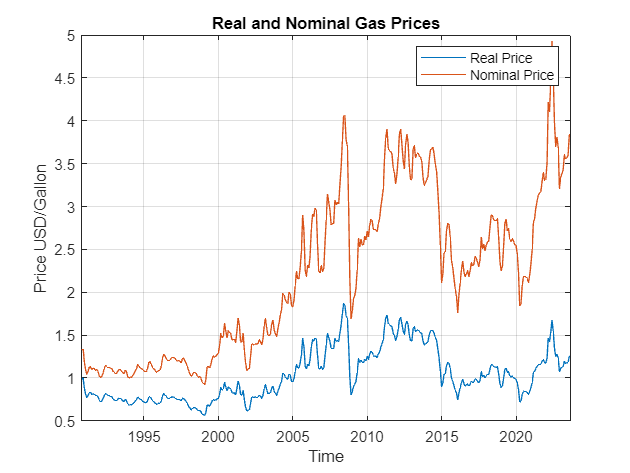

% Real price
data.real_price = (data.nominal_price ./ data.CPI) * 100;

% Plotting the data
figure(1);
plot(data.date, data.real_price, data.date, data.nominal_price);
legend('Real Price', 'Nominal Price');
xlabel('Time');
ylabel('Price USD/Gallon');
title('Real and Nominal Gas Prices');
grid on;

**3) From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).**

%% section 3
% log(real_price)
data.log_real_price = log(data.real_price);

% sample data 
sample_data = data(timerange("01-Nov-1990","02-Dec-2014"), :)

sample_data = 290×4 timetable
       date        nominal_price     CPI     real_price    log_real_price
    ___________    _____________    _____    __________    ______________

    01-Nov-1990        1.324        133.7     0.99028        -0.0097708  
    01-Dec-1990        1.341        134.2     0.99925       -0.00074543  
    01-Jan-1991         1.18        134.7     0.87602          -0.13237  
    01-Feb-1991       1.0942        134.8     0.81176          -0.20855  
    01-Mar-1991         1.04        134.8     0.77151           -0.2594  
    01-Apr-1991       1.0762        135.1      0.7966          -0.22741  
    01-May-1991       1.1258        135.6      0.8302          -0.18609  
    01

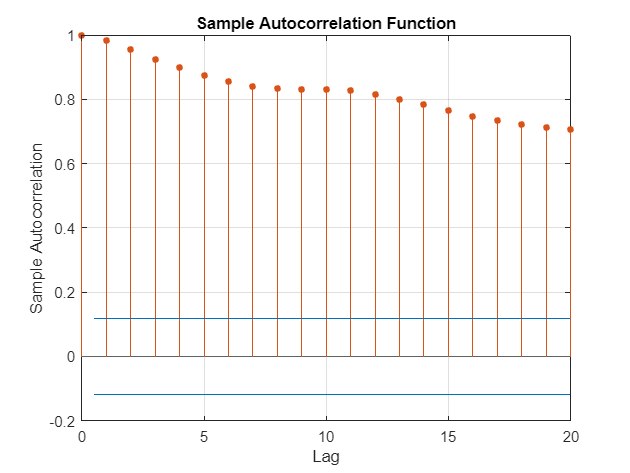

% from econometrics toolbox
% ACF log real price
[acf, lags] = autocorr(sample_data.log_real_price); 
autocorr(sample_data.log_real_price)

Since the positive and large autocorrelations that slowly decreases, we see the presence of a trend.

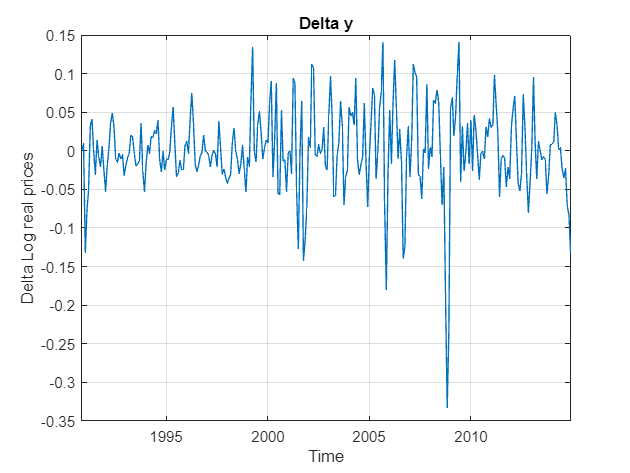

% compute delta_y = (y_t - y_t-1)
time = sample_data.date(2:end);
time = [datetime("01-Nov-1990", 'InputFormat', 'dd-MMM-yyyy'); time]; % add the first date at the beginning to match the series length 
delta_log_rp = diff(sample_data.log_real_price); % compute the difference
delta_log_rp = [0; delta_log_rp]; % add zero value at the beginning to match the series length

sample_data.delta_log_rp = delta_log_rp;
data.delta_log_rp = [0; diff(data.log_real_price)];

plot(sample_data.date, sample_data.delta_log_rp); title('Delta y'); grid on;
xlabel('Time'); ylabel('Delta Log real prices')

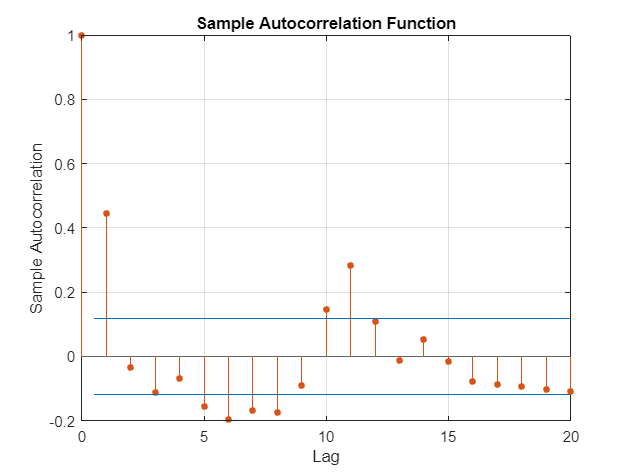

% ACF log real price
autocorr(sample_data.delta_log_rp(2:end))

We can see the presence of seasonality inside the series of the Gas prices variation.

**4) Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable**

"Many observed time series exhibit serial autocorrelation; that is, linear association between lagged observations. This suggests past observations might predict current observations. The autoregressive (AR) process models the conditional mean of *yt* as a function of past observations, *yt*−1,*yt*−2,…,*yt*−*p*. An AR process that depends on *p* past observations is called an AR model of degree *p*, denoted by AR(*p*)." 

(source: https://it.mathworks.com/help/econ/specify-ar-models.html)

%% section 4
clc, close all


% Fitting AR(1) model for log real price

mdl_lrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_lrp = estimate(mdl_lrp, sample_data.log_real_price(1:end-1)); % Estimate the model parameters

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0003354      0.0035073       0.095627        0.92382
    AR{1}         0.98557        0.01177         83.737              0
    Variance    0.0029837     0.00014458         20.637     1.2903e-94



coef_lrp = est_lrp.AR{1}; % Get the coefficient associated with the lagged dependent variable


% Fitting AR(1) for delta lrp

mdl_dlrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_dlrp = estimate(mdl_dlrp, sample_data.delta_log_rp(1:end-1)); % Estimate the model parameters

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00028516      0.0030514       0.093451        0.92555
    AR{1}           0.4454       0.030699         14.508     1.0711e-47
    Variance     0.0024129     0.00013383          18.03     1.1264e-72



coef_dlrp = est_dlrp.AR{1}; % Get the coefficient associated with the lagged dependent variable



**5)  Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)**

ARIMA models have three key parameters: the order of autoregression, the degree of differencing and the order of the moving average. These parameters are represented as p, d, and q, respectively.

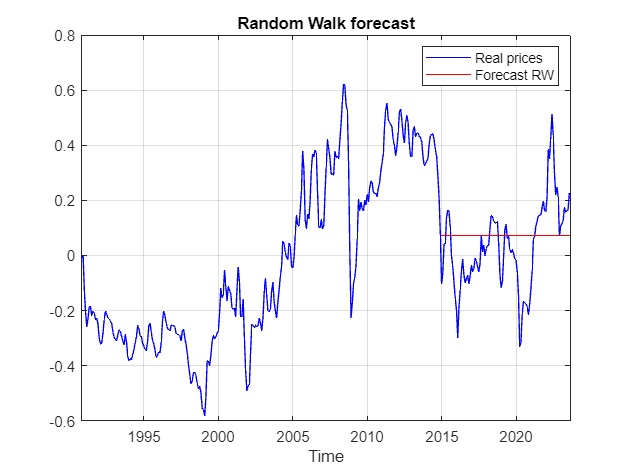

% Random Walk (no drift)
% forcasted values are all equal to y_t(t = "01-Dec-2014")
forecasted_values_RW = [NaN(1, 290), ones(1, 105) * data.log_real_price(290)]; % array of NaN until Dec-2014 (290)


plot(data.date, data.log_real_price', '-b', ...     % plot real prices
    data.date, forecasted_values_RW, '-r');         % plot forcast
title('Random Walk forecast'); legend('Real prices', 'Forecast RW'); xlabel('Time'); grid on

ARIMA models

The series need to be stationary: mean, variance, and autocorrelation structure remain constant over time.

T = height(data); % sample size
T0 = find(data.date=='01-Dec-2014'); % start of estimation sample
h = 1; % forecast horizon
fore_111 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(1,1,1)
fore_110 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(1,1,0)
fore_011 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(0,1,1)
fore_rw = NaN(T, h);  % Tx1 vector to store forecasts for Random Walk

m_111 = arima(1, 1, 1); % ARIMA(1,1,1) model 
m_110 = arima(1, 1, 0); % ARIMA(1,1,0) model
m_011 = arima(0, 1, 1); % ARIMA(0,1,1) model
m_rw = arima(0, 1, 0);  % Random Walk model

jj = T0; % initialize while loop
while jj < T % repeat the following until jj < T
    % ARIMA(1,1,1)
    m_111 = estimate(m_111, data.log_real_price(1:jj)); % estimate ARIMA(1,1,1)
    fore_111(jj+1) = forecast(m_111, h, data.log_real_price(1:jj)); % forecast ARIMA(1,1,1)

    % ARIMA(1,1,0)
    m_110 = estimate(m_110, data.log_real_price(1:jj)); % estimate ARIMA(1,1,0)
    fore_110(jj+1) = forecast(m_110, h, data.log_real_price(1:jj)); % forecast ARIMA(1,1,0)

    % ARIMA(0,1,1)
    m_011 = estimate(m_011, data.log_real_price(1:jj)); % estimate ARIMA(0,1,1)
    fore_011(jj+1) = forecast(m_011, h, data.log_real_price(1:jj)); % forecast ARIMA(0,1,1)

    % Random Walk
    m_rw = estimate(m_rw, data.log_real_price(1:jj)); % estimate Random Walk model
    fore_rw(jj+1) = forecast(m_rw, h, data.log_real_price(1:jj)); % forecast Random Walk

    jj = jj + 1; % increase loop index
end

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0003468      0.0042378      -0.081834        0.93478
    AR{1}          0.13704       0.077908          1.759        0.07858
    MA{1}          0.46159       0.077173         5.9813     2.2138e-09
    Variance     0.0022499      0.0001357          16.58     9.7371e-62



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -5.4073e-05      0.0030608      -0.017666        0.98591
    AR{1}           0.45472       0.030854         14.738     3.7005e-49
    Variance      0.0024359     0.00013617         17.889      1.447e-71



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.000484       0.004469       -0.1083         0.91376
    MA{1}         0.54524       0.034884         15.63      4.5324e-55
    Variance    0.0022664     0.00013692        16.553      1.5327e-61



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00028405      0.0035267       0.080543        0.93581
    Variance     0.0030548     0.00014075         21.703     1.919e-104



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   



 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    -0.0003468          0             -Inf         0   
    Variance     0.0022499          0              Inf         0   



 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic    PValue
                ___________    _____________    __________    ______

    Constant    -5.4073e-05          0             -Inf         0   
    Variance      0.0024359          0              Inf         0   



 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue
                _________    _____________    __________    ______

    Constant    -0.000484          0             -Inf         0   
    Variance    0.0022664          0              Inf         0   



 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    0.00028405          0             Inf          0   
    Variance     0.0030548          0             Inf          0   





% forecast errors
uhat_111 = data.log_real_price(T0+1:end) - fore_111(T0+1:end); % forecast errors for ARIMA(1,1,1)
uhat_110 = data.log_real_price(T0+1:end) - fore_110(T0+1:end); % forecast errors for ARIMA(1,1,0)
uhat_011 = data.log_real_price(T0+1:end) - fore_011(T0+1:end); % forecast errors for ARIMA(0,1,1)
uhat_rw = data.log_real_price(T0+1:end) - fore_rw(T0+1:end); % forecast errors for Random Walk



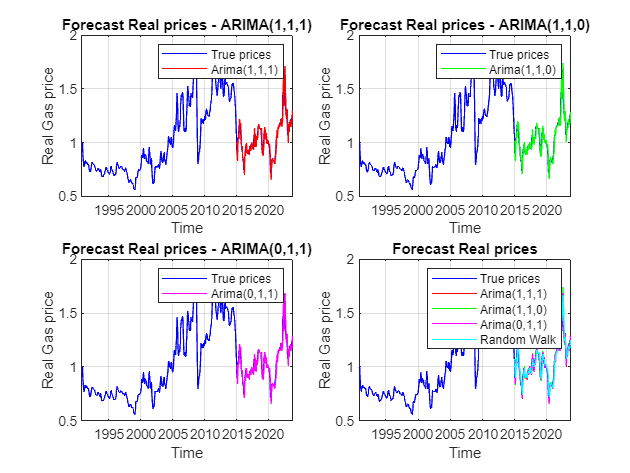

plot(data.date, data.real_price, '-b', ...
    data.date, exp(fore_111), '-r', ...
    data.date, exp(fore_110), '-g', ...
    data.date, exp(fore_011), '-m', ...
    data.date, exp(fore_rw), '-c');
title('Forecast Real prices'); legend('True prices', 'Arima(1,1,1)', 'Arima(1,1,0)', 'Arima(0,1,1)', 'Random Walk');
xlabel('Time'); ylabel('Real Gas price'); grid on;

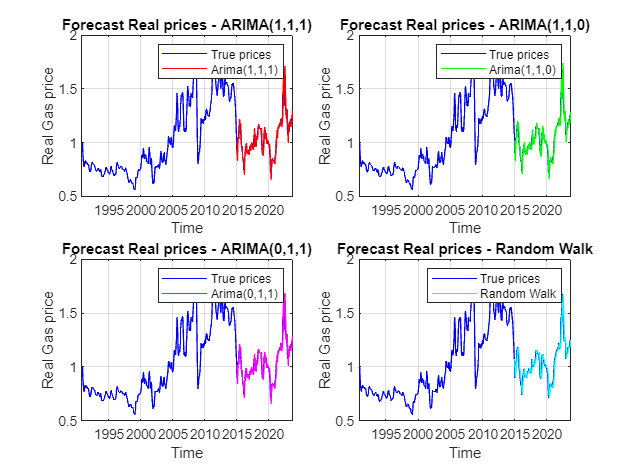

figure;
subplot(2,2,1);
plot(data.date, data.real_price, '-b', ...
    data.date, exp(fore_111), '-r');
title('Forecast Real prices - ARIMA(1,1,1)');
legend('True prices', 'Arima(1,1,1)');
xlabel('Time'); ylabel('Real Gas price');
grid on;

% Plot for ARIMA(1,1,0)
subplot(2,2,2);
plot(data.date, data.real_price, '-b', ...
    data.date, exp(fore_110), '-g');
title('Forecast Real prices - ARIMA(1,1,0)');
legend('True prices', 'Arima(1,1,0)');
xlabel('Time'); ylabel('Real Gas price');
grid on;

% Plot for ARIMA(0,1,1)
subplot(2,2,3);
plot(data.date, data.real_price, '-b', ...
    data.date, exp(fore_011), '-m');
title('Forecast Real prices - ARIMA(0,1,1)');
legend('True prices', 'Arima(0,1,1)');
xlabel('Time'); ylabel('Real Gas price');
grid on;

% Subplot for Random Walk
subplot(2,2,4);
plot(data.date, data.real_price, '-b', ...
    data.date, exp(fore_rw), '-c');
title('Forecast Real prices - Random Walk');
legend('True prices', 'Random Walk');
xlabel('Time'); ylabel('Real Gas price');
grid on;

**7) Compute the mean squared forecast error and comment.**

mse_111 = immse(exp(fore_111(T0+1:end)), data.real_price(T0+1:end));
mse_110 = immse(exp(fore_110(T0+1:end)), data.real_price(T0+1:end));
mse_011 = immse(exp(fore_011(T0+1:end)), data.real_price(T0+1:end));
mse_rw = immse(exp(fore_rw(T0+1:end)), data.real_price(T0+1:end));

% Create a table
model_names = {'ARIMA(1,1,1)', 'ARIMA(1,1,0)', 'ARIMA(0,1,1)', 'Random Walk'};
mse_values = [mse_111; mse_110; mse_011; mse_rw];

result_table = table(model_names', mse_values, 'VariableNames', {'Model', 'MSE'});

% Display the table
disp(result_table);

         Model             MSE   
    ________________    _________

    {'ARIMA(1,1,1)'}    0.0039098
    {'ARIMA(1,1,0)'}    0.0039419
    {'ARIMA(0,1,1)'}    0.0038064
    {'Random Walk' }    0.0042069

